Question: How long will a flu outbreak in the future last?

This question involves prediction. We can not see into the future, thus we have to use data from the past in order to make an educated guess. 

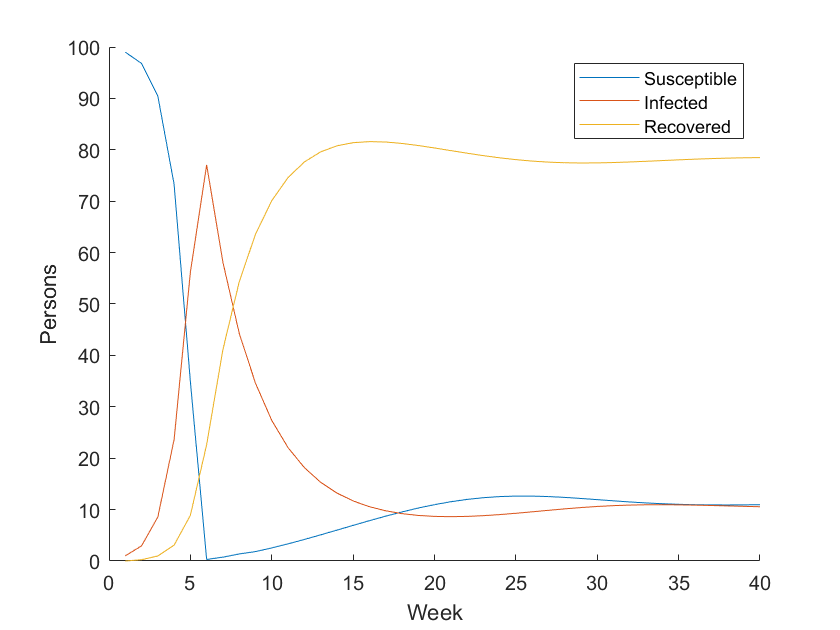

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
beta = 1 / 45;
gamma = 1/4;
alpha = 1/30;
num_week = 40;
% Run simulation
[S, I, R, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
%(s, i, r, beta, r_time, s_time, infected_list, step)
hold off;

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

tab_data_validate = 18×2 table
    W     I 
    __    __

     1     2
     2     3
     3     5
     4     8
     5    11
     6    16
     7    20
     8    23
     9    23
    10    20
    11    16
    12    12
    13     8
    14     6
    15     4
    16     3


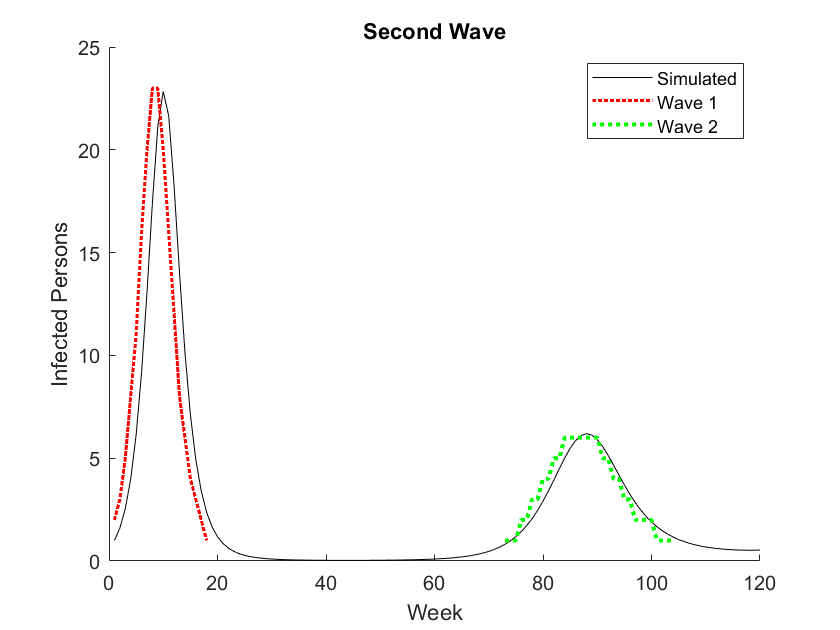


% Configure the simulation

s_0 = 99;
i_0 = 1;
r_0 = 0;
beta = 1 / 90;
gamma = 1/2;
alpha = 1/60;
num_week = 120;

% Run simulation
[S_fit, I_fit, R_fit, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W, I_fit, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Second Wave")

% TODO: Compute total persons, plot
% HINT 1: You can copy-paste plotting code from above!
% HINT 2: Your plot might end up looking "boring"....
total = S_fit + I_fit + R_fit

total =   100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000




[S_fit, I_fit, R_fit, W_fit, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot the fitted simulation
figure(1); clf; hold on;
plot(W_fit, total, 'k-'); label2 = "Total Persons";

xlabel("Week")
ylabel("Total Persons")
legend({label1, label2})

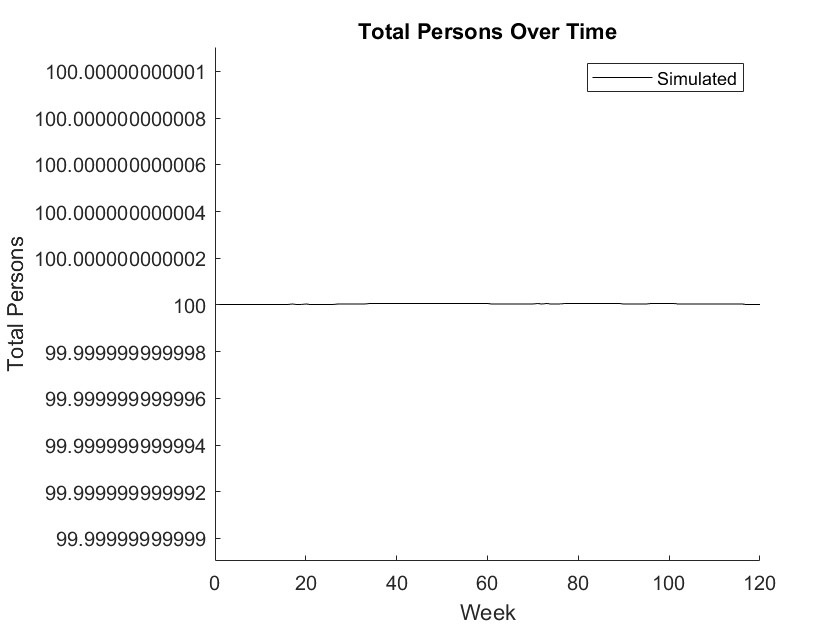

title("Total Persons Over Time")

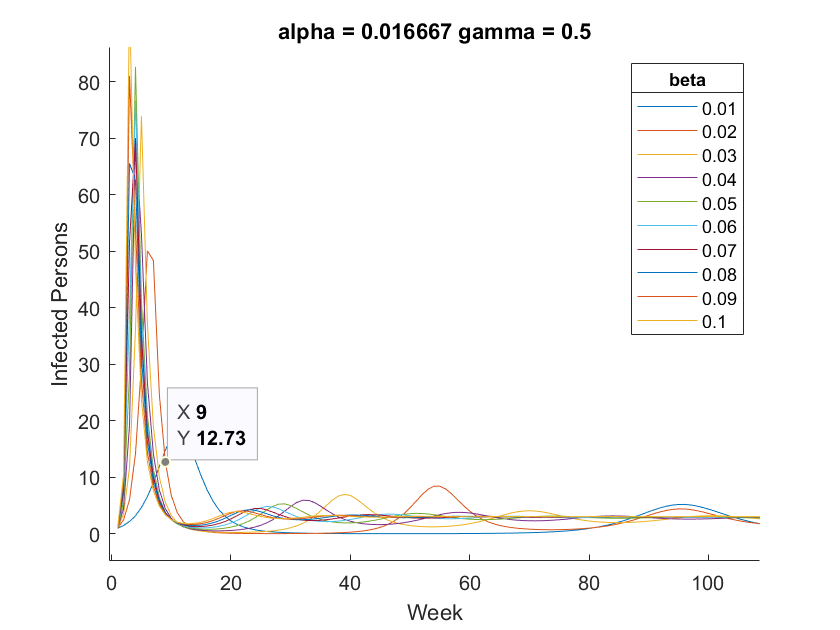

%run beta_sweep
beta_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);

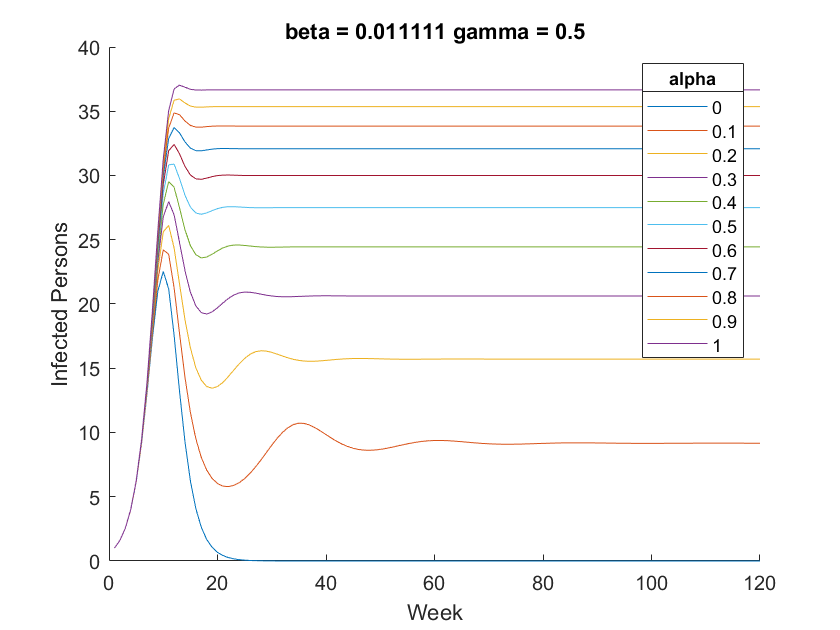

alpha_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);

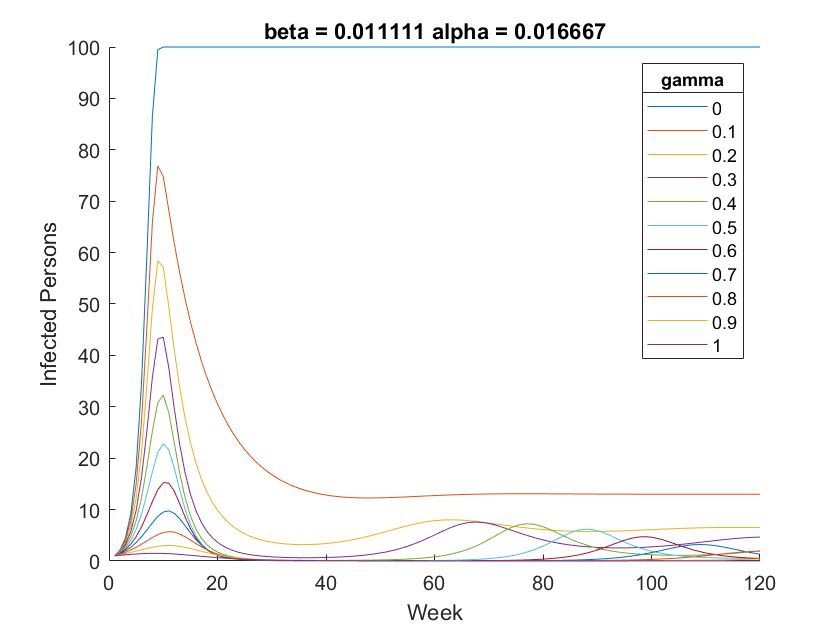

gamma_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);


beta_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week);
alpha_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week);
gamma_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week);